# Activity 10: Elementary Cellular Automaton

The task is to demonstrate Wolfram's 1D CA models (https://mathworld.wolfram.com/ElementaryCellularAutomaton.html). This is the simplest class of one-dimensional cellular automata.

For this purpose, I created a function CA1D to implement the 1D Cellular Automata. The inputs are:

- rule - the specific rule that we want to implement

- timestep - the number of timesteps/generations that we want 

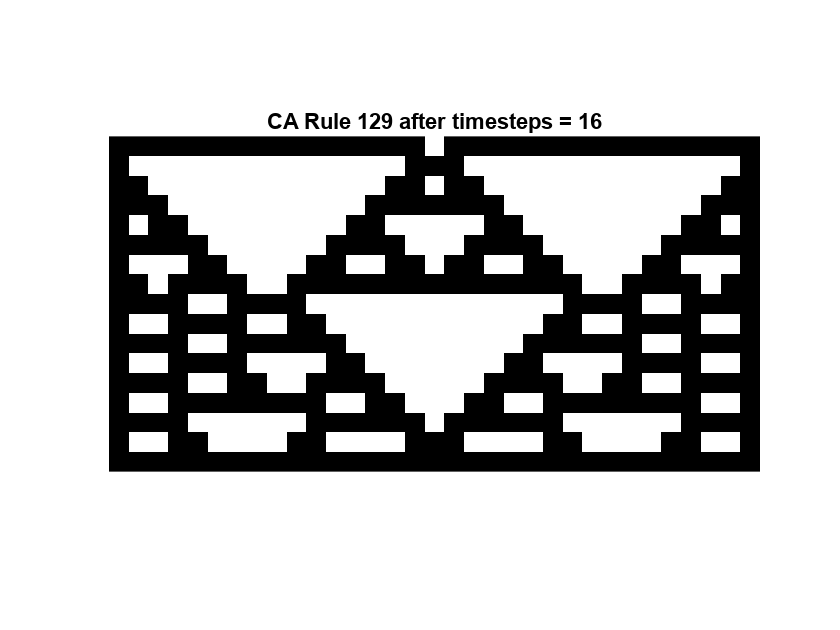

clear;close;
CA1D(129, 16);

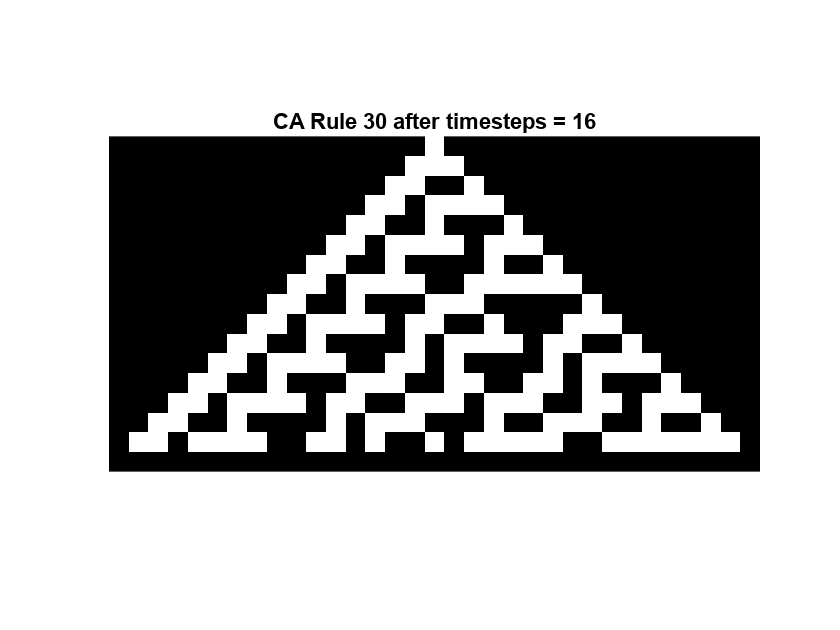

clear;close;
CA1D(30, 16);

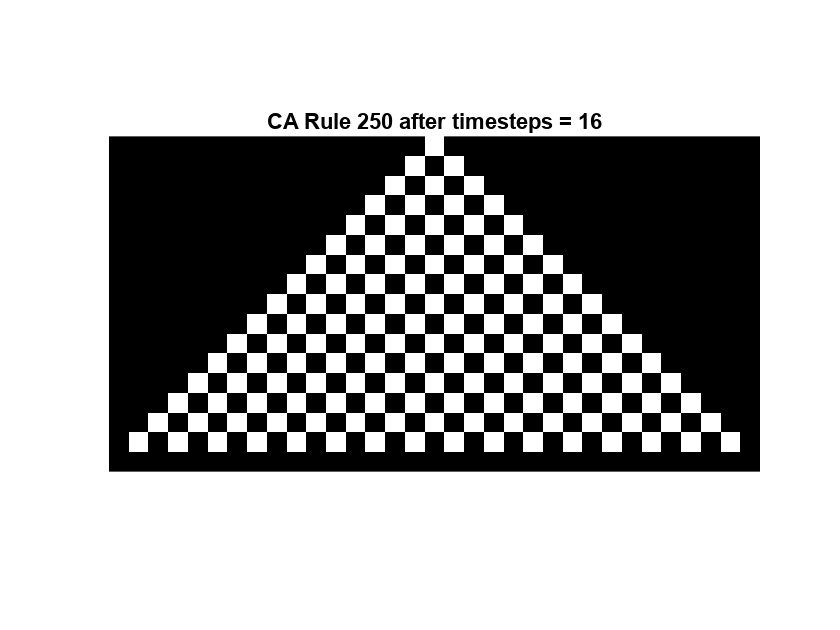

clear;close;
CA1D(250, 16);

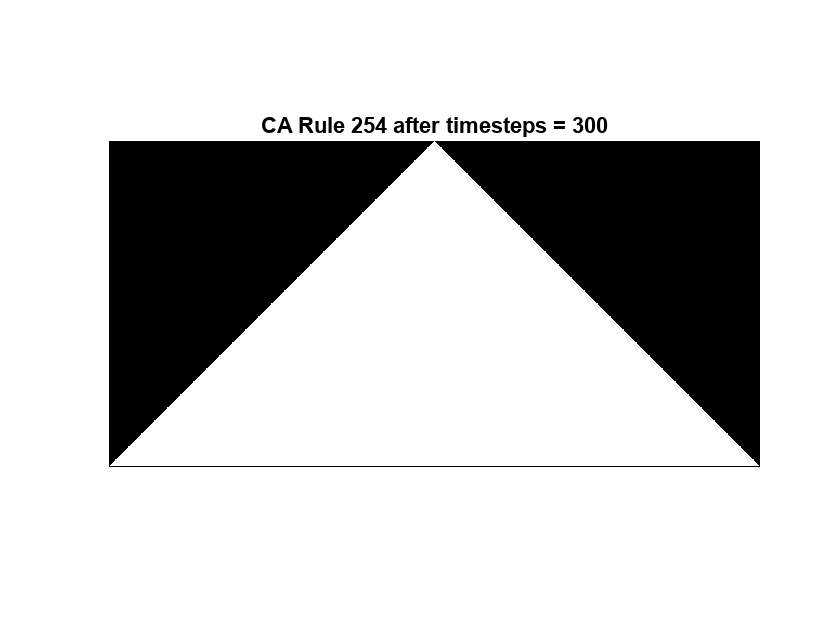

clear;close;
CA1D(254,300);

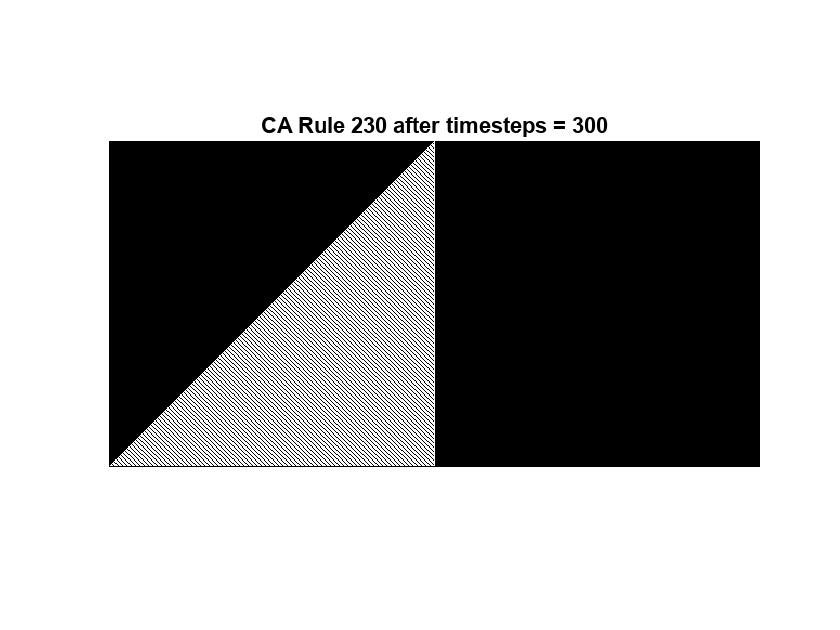

clear;close;
CA1D(230, 300);

function a = CA1D(rule, timestep)
    % Convert decimal rule to 8-bit binary
    %then convert to numeric array
    ruleset = dec2bin(rule, 8) - '0';
    
    % Set the grid
    grid = zeros(timestep+1, timestep*2+1);

    %setting the "on" cell in the middle colum of the top row
    grid(1, timestep+1) = 1;

    %possible configurations of a 3-cell neighborhood 
    %0 - on and 1 - off
    Prev = [1 1 1; 1 1 0; 1 0 1; 1 0 0; 0 1 1; 0 1 0; 0 0 1; 0 0 0];
    
    % Loop over timesteps/generations
    for i = 1:timestep
        a = imagesc(grid); colormap(gray);   % Display grid
        title(['CA Rule ' num2str(rule) ' after timesteps = ' num2str(timestep)]);
        axis image;
        axis off;
        drawnow;
        nextGrid = grid;

        % Loop over assigning value to next generation
        for j = 2:(timestep*2)
            neighborhood = grid(i, j-1:j+1);
            for k = 1:8
                if isequal(neighborhood, Prev(k, :))
                    nextGrid(i+1, j) = ruleset(k);
                    break;
                end
            end
        end
        grid = nextGrid;
    end
end